clc; clear; close all;
addpath z_toolbox
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_IEDxcD_polyfit_delays.mat'), ...
    'IEDxcDas', 'NAxcDas');
x = IEDxcDas; y = NAxcDas;
[forest, ~, scores] = iforest([x, y], "ContaminationFraction", 0.1);
x = x(scores <= forest.ScoreThreshold);
y = y(scores <= forest.ScoreThreshold);
[~, Curve, ~] = f_polyfit(x, y, 1);
[R, P] = corr(x, y, 'type', 'Spearman');
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(x, y, 6); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x)-1, max(x)+1]); ylim([min(y)-1, max(y)+1]);
xlabel('IED-LC Delay (ms)'); ylabel('NA-LC Delay (ms)');
disp(['r = ', num2str(R), ' p=', num2str(P)]);

r = 0.33759 p=0


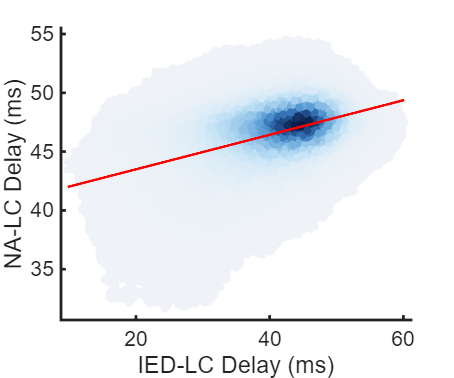

set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);